% set index = 1 in MIP_import
MIP_import

function C = concatenateAndFill(varargin)
    % 各列の長さを取得し、最大の長さを求める
    maxLength = max(cellfun(@length, varargin));

    % 各列について、足りない部分をNaNで埋める
    paddedColumns = cellfun(@(x) [x; NaN(maxLength-length(x),1)], varargin, 'UniformOutput', false);

    % すべての列を横に結合する
    C = horzcat(paddedColumns{:});
end

Figure 2 A

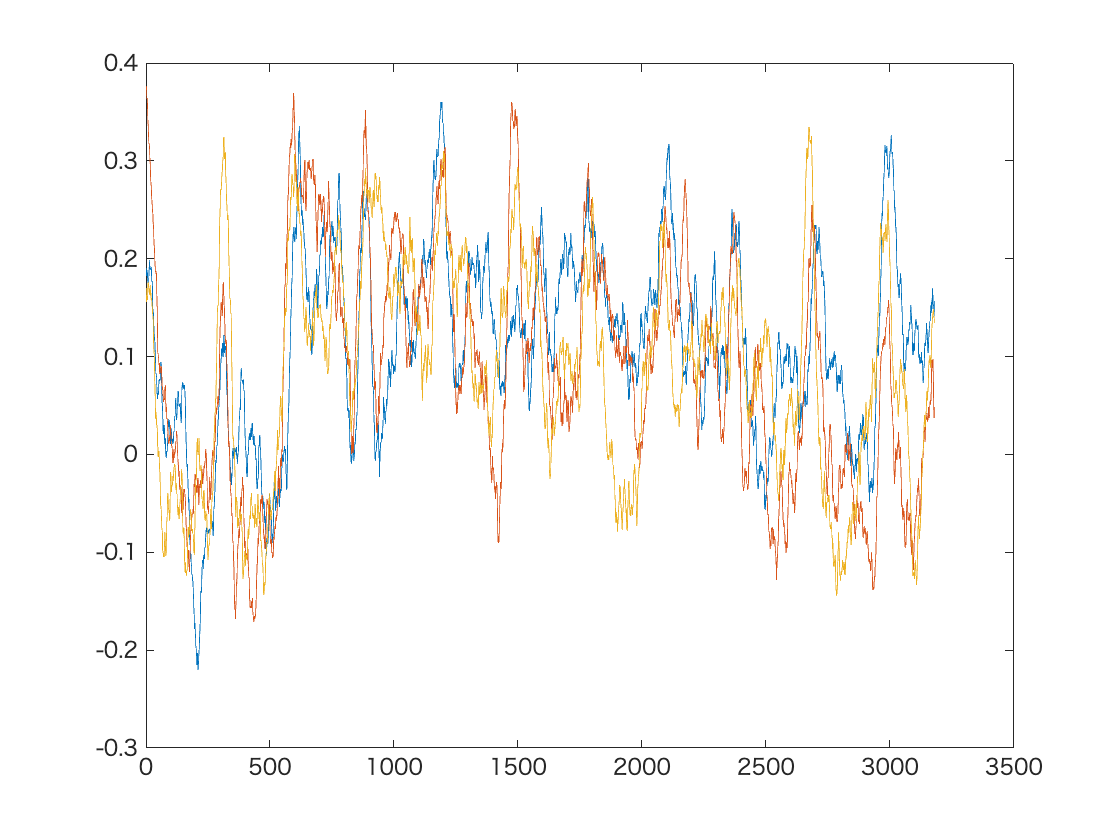

active_phi = zeros(18, time);
passive_phi = zeros(18, time);
control_phi = zeros(18, time);

for ind = 1 :18
    active_phi(ind, :) = movmean(active_MIP_PHI(ind, :), 50);
    passive_phi(ind, :) = movmean(passive_MIP_PHI(ind, :), 50);
    control_phi(ind, :) = movmean(control_MIP_PHI(ind, :), 50);
end

% Blue-Moderate: Red-Difficult: Yellow-Easy
plot(mean(active_phi))
hold on
plot(mean(passive_phi))
plot(mean(control_phi))
hold off


result = [mean(active_phi);mean(passive_phi);mean(control_phi)].';
%writematrix(result, "SF_MIP_series_" + num2str(interval) + ".csv");

MIP_PHI comparison

times = 1: time1;

inter = size(active_MIP(:,times), 2);
active_bf = reshape(active_MIP(:, times), [1, inter*18]);
passive_bf = reshape(passive_MIP(:, times), [1, inter*18]);
control_bf = reshape(control_MIP(:, times), [1, inter*18]);

active_mip_bf = reshape(active_MIP_PHI(:, times), [1, inter*18]);
passive_mip_bf = reshape(passive_MIP_PHI(:, times), [1, inter*18]);
control_mip_bf = reshape(control_MIP_PHI(:, times), [1, inter*18]);

times = time1:time2;

inter = size(active_MIP(:,times), 2);
active_task = reshape(active_MIP(:, times), [1, inter*18]);
passive_task = reshape(passive_MIP(:, times), [1, inter*18]);
control_task = reshape(control_MIP(:, times), [1, inter*18]);

active_mip_task = reshape(active_MIP_PHI(:, times), [1, inter*18]);
passive_mip_task = reshape(passive_MIP_PHI(:, times), [1, inter*18]);
control_mip_task = reshape(control_MIP_PHI(:, times), [1, inter*18]);

times = time2:time;

inter = size(active_MIP(:,times), 2);
active_af = reshape(active_MIP(:, times), [1, inter*18]);
passive_af = reshape(passive_MIP(:, times), [1, inter*18]);
control_af = reshape(control_MIP(:, times), [1, inter*18]);

active_mip_af = reshape(active_MIP_PHI(:, times), [1, inter*18]);
passive_mip_af = reshape(passive_MIP_PHI(:, times), [1, inter*18]);
control_mip_af = reshape(control_MIP_PHI(:, times), [1, inter*18]);


data1 = control_mip_bf.';
data2 =  control_mip_task.';

[p,h,stats] = ranksum(data1, data2)

p = 1.5406e-29

h = logical
   1


stats = フィールドをもつ struct :
       zval: -11.2859
    ranksum: 207798654


W = stats.ranksum;
n1 = min(length(data1), length(data2))

n1 = 10314

U = W - n1 * (n1 + 1) / 2

U = 154604199

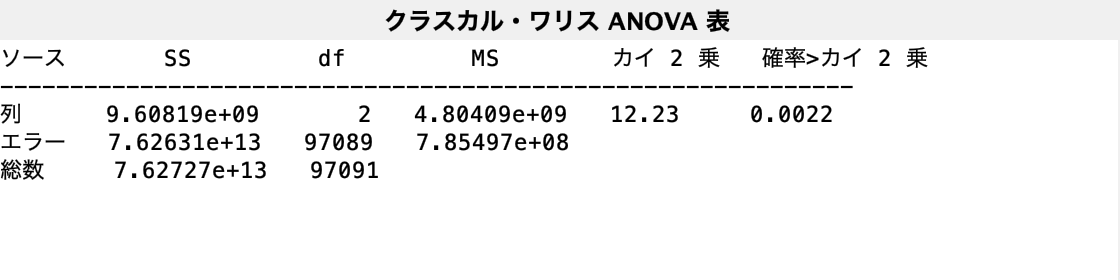

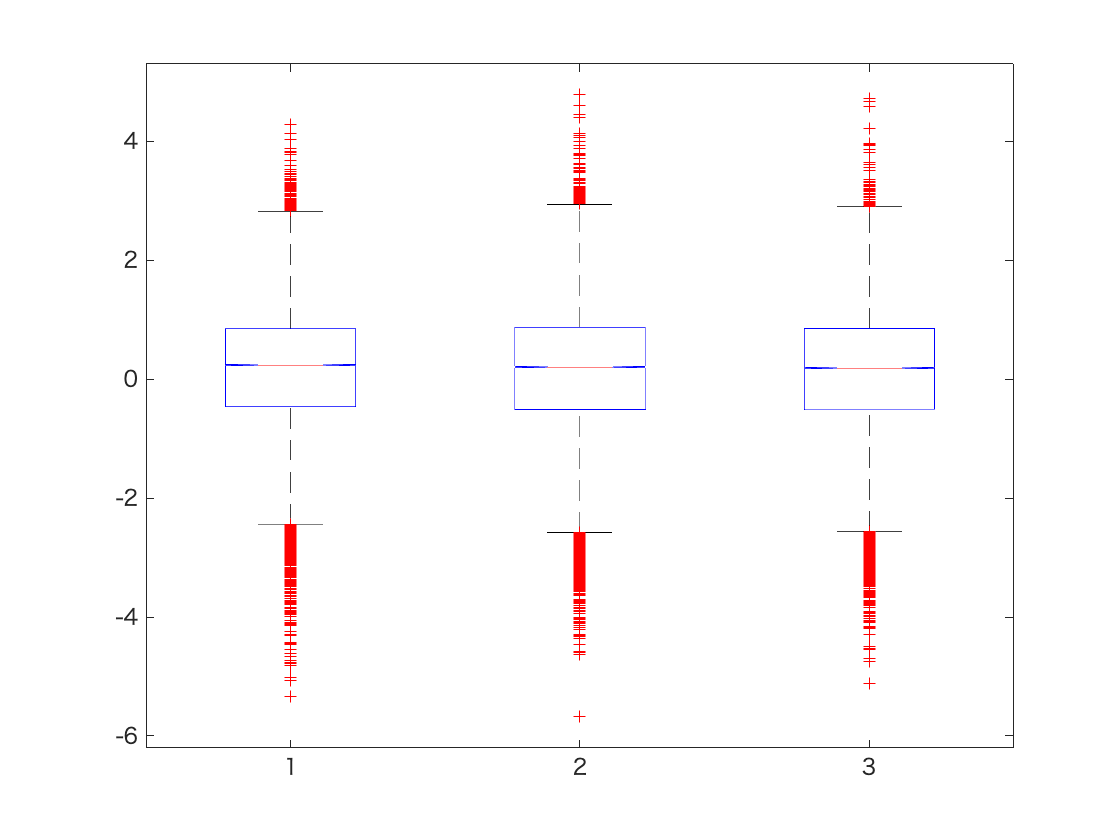

p = 0.0022

tbl = 4×6 の cell 配列
    {'ソース'}    {'SS'        }    {'df'   }    {'MS'        }    {'カイ 2 乗'}    {'確率>カイ 2 乗'}
    {'列'   }    {[9.6082e+09]}    {[    2]}    {[4.8041e+09]}    {[ 12.2307]}    {[       0.0022]}
    {'エラー'}    {[7.6263e+13]}    {[97089]}    {[7.8550e+08]}    {0×0 double}    {0×0 double     }
    {'総数' }    {[7.6273e+13]}    {[97091]}    {0×0 double  }    {0×0 double}    {0×0 double     }


stats = フィールドをもつ struct :
       gnames: [3×1 char]
            n: [32364 32364 32364]
       source: 'kruskalwallis'
    meanranks: [4.8908e+04 4.8590e+04 4.8142e+04]
         sumt: 2820


X = [active_mip_task;passive_mip_task;control_mip_task].';
[p,tbl,stats] = kruskalwallis(X)

c = multcompare(stats,"CriticalValueType","dunn-sidak")

メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


c = 1.0e+03 *

    0.0010    0.0020   -0.2072    0.3189    0.8450    0.0004
    0.0010    0.0030    0.2408    0.7669    1.2930    0.0000
    0.0020    0.0030   -0.0781    0.4480    0.9741    0.0001


Figure 2 B

% set index = 2 in MIP_import
MIP_import

MIP_type = unique([unique_without_nan(active_MIP); ...
    unique_without_nan(passive_MIP); unique_without_nan(control_MIP)]);

MIP_frequency_Prev = zeros(3, size(MIP_type, 1), 18);
MIP_frequency_Stim = zeros(3, size(MIP_type, 1), 18);
MIP_frequency_Post = zeros(3, size(MIP_type, 1), 18);

t1 = times(2);  t2= times(3); t_end=times(1);
t1_interval = 1:t1; t2_interval = t1:t2; t3_interval = t2:t_end;

T1 = length(t1_interval);
T2 = length(t2_interval);
T3 = length(t3_interval);

for ind = 1 :18
    for i = 1 : length(MIP_type)
        MIP_frequency_Prev(1, i, ind) = sum(active_MIP(ind, t1_interval)==MIP_type(i))/T1;
        MIP_frequency_Prev(2, i, ind) = sum(passive_MIP(ind, t1_interval)==MIP_type(i))/T1;
        MIP_frequency_Prev(3, i, ind) = sum(control_MIP(ind, t1_interval)==MIP_type(i))/T1;
    
        MIP_frequency_Stim(1, i, ind) = sum(active_MIP(ind, t2_interval)==MIP_type(i))/T2;
        MIP_frequency_Stim(2, i, ind) = sum(passive_MIP(ind, t2_interval)==MIP_type(i))/T2;
        MIP_frequency_Stim(3, i, ind) = sum(control_MIP(ind, t2_interval)==MIP_type(i))/T2;
    
        MIP_frequency_Post(1, i, ind) = sum(active_MIP(ind, t3_interval)==MIP_type(i))/T3;
        MIP_frequency_Post(2, i, ind) = sum(passive_MIP(ind, t3_interval)==MIP_type(i))/T3;
        MIP_frequency_Post(3, i, ind) = sum(control_MIP(ind, t3_interval)==MIP_type(i))/T3;
    end
end

mean_stim_bar = zeros(length(MIP_type), 3);
MIP_list = [];

for j = 1 : length(MIP_type)
    count = [0, 0, 0];
    for i = 1 : 3
        A = reshape(MIP_frequency_Stim(i, j, :) - MIP_frequency_Prev(i, j, :), [18, 1]);
        if swtest(A, 0.05) == 0
            [s, p] = ttest(A, zeros(18,1));
        else
            [p, s] = ranksum(A, zeros(18,1));
        end
        
        mean_stim_bar(j, i) = mean(A);
        if p < 0.05
            count(i) = 1;
        end
    end
    if sum(count) >= 1 && mean(abs(mean_stim_bar(j, :))) > 0.005
         MIP_list = [MIP_list, j];
         bit_seq_rev(MIP_type(j))
         mean_stim_bar(j, :)
        count
    end
end

ans = "Cz"

ans =     0.0132    0.0132    0.0057


count =      1     0     0


ans = "ECG"

ans =     0.1005    0.0942    0.0817


count =      1     1     1


ans = "EDA"

ans =    -0.1195   -0.1424   -0.0795


count =      1     1     1


ans = 1×2 の string 配列
    "ECG"    "EDA"


ans =    -0.0101   -0.0056   -0.0084


count =      0     0     1


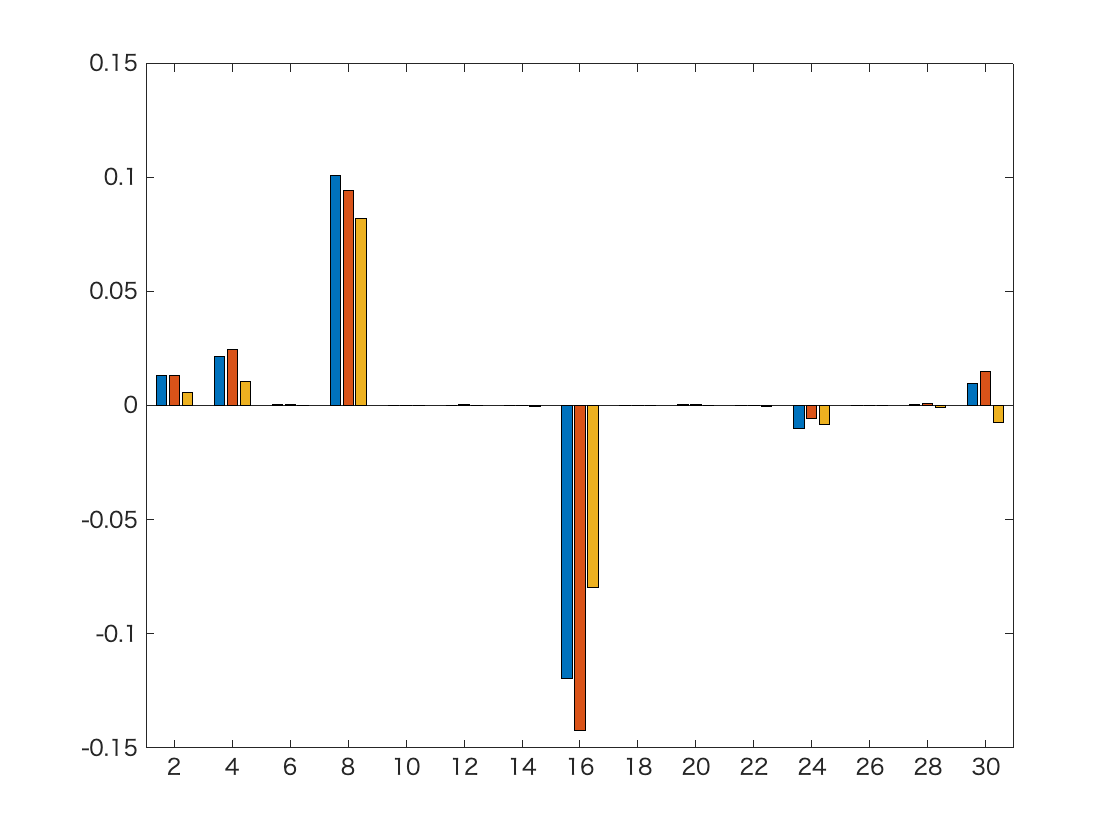


% Blue-Moderate: Red-Difficult: Yellow-Easy
% We pick up P <.05.
bar(MIP_type , mean_stim_bar)

ECG, EDA cut for task difference

cp1 = MIP_type(4);
bit_seq_rev(cp1)

ans = "ECG"


A = reshape(MIP_frequency_Stim(1, 4, :) - MIP_frequency_Prev(1, 4, :), [18, 1]);
B = reshape(MIP_frequency_Stim(2, 4, :) - MIP_frequency_Prev(2, 4, :), [18, 1]);
C = reshape(MIP_frequency_Stim(3, 4, :) - MIP_frequency_Prev(3, 4, :), [18, 1]);

[H, pValue, W] = swtest([A; B; C])

H = logical
   0


pValue = 0.2168

W = 0.9712

writematrix([A, B, C], "ANOVA.csv")

cp1 = MIP_type(8);
bit_seq_rev(cp1)

ans = "EDA"


A = reshape(MIP_frequency_Stim(1, 8, :) - MIP_frequency_Prev(1, 8, :), [18, 1]);
B = reshape(MIP_frequency_Stim(2, 8, :) - MIP_frequency_Prev(2, 8, :), [18, 1]);
C = reshape(MIP_frequency_Stim(3, 8, :) - MIP_frequency_Prev(3, 8, :), [18, 1]);

[H, pValue, W] = swtest([A; B; C])

H = logical
   0


pValue = 0.1457

W = 0.9685

writematrix([A, B, C], "ANOVA.csv")

Figure 2 - Table 1 : Each MIP-cut difference

cp1 = MIP_type(8);
bit_seq_rev(cp1)

ans = "EDA"

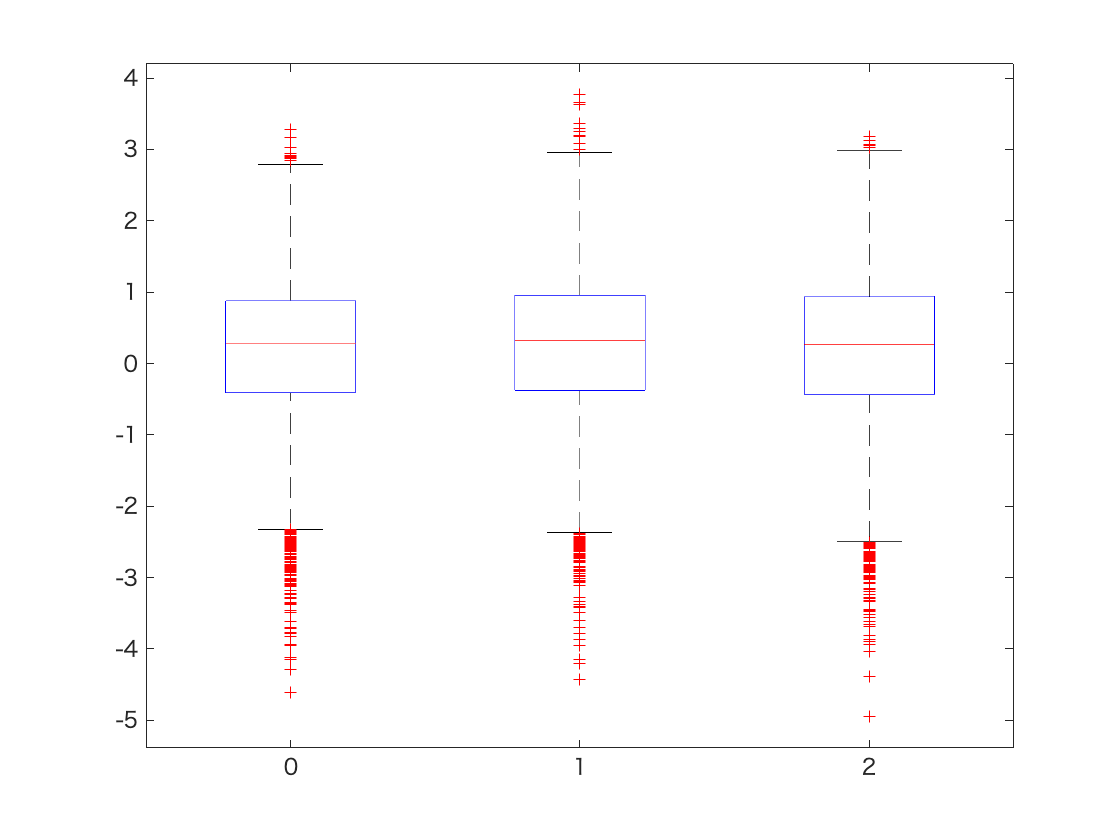


mip_active_bf = active_mip_bf(find(active_bf==cp1));
mip_passive_bf = passive_mip_bf(find(passive_bf==cp1));
mip_control_bf = control_mip_bf(find(control_bf==cp1));

mip_active_task = active_mip_task(find(active_task==cp1));
mip_passive_task = passive_mip_task(find(passive_task==cp1));
mip_control_task = control_mip_task(find(control_task==cp1));

mip_active_af = active_mip_af(find(active_af==cp1));
mip_passive_af = passive_mip_af(find(passive_af==cp1));
mip_control_af = control_mip_af(find(control_af==cp1));

x1 = (mip_active_task-mean(mip_active_bf)).';
x2 = (mip_passive_task-mean(mip_passive_bf)).';
x3 = (mip_control_task-mean(mip_control_bf)).';
x = [x1; x2; x3];
g = [zeros(length(x1), 1); ones(length(x2), 1); 2*ones(length(x3), 1)];
boxplot(x, g)


[mean(x1), mean(x2), mean(x3)]

ans =     0.1983    0.2645    0.2126


[std(x1), std(x2), std(x3)]

ans =     0.9806    1.0167    1.0480


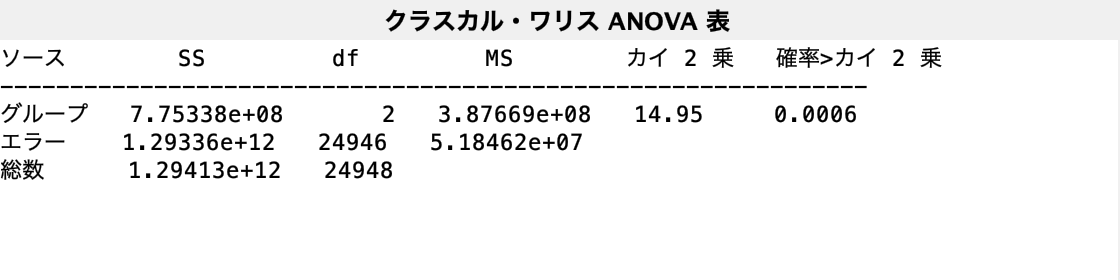

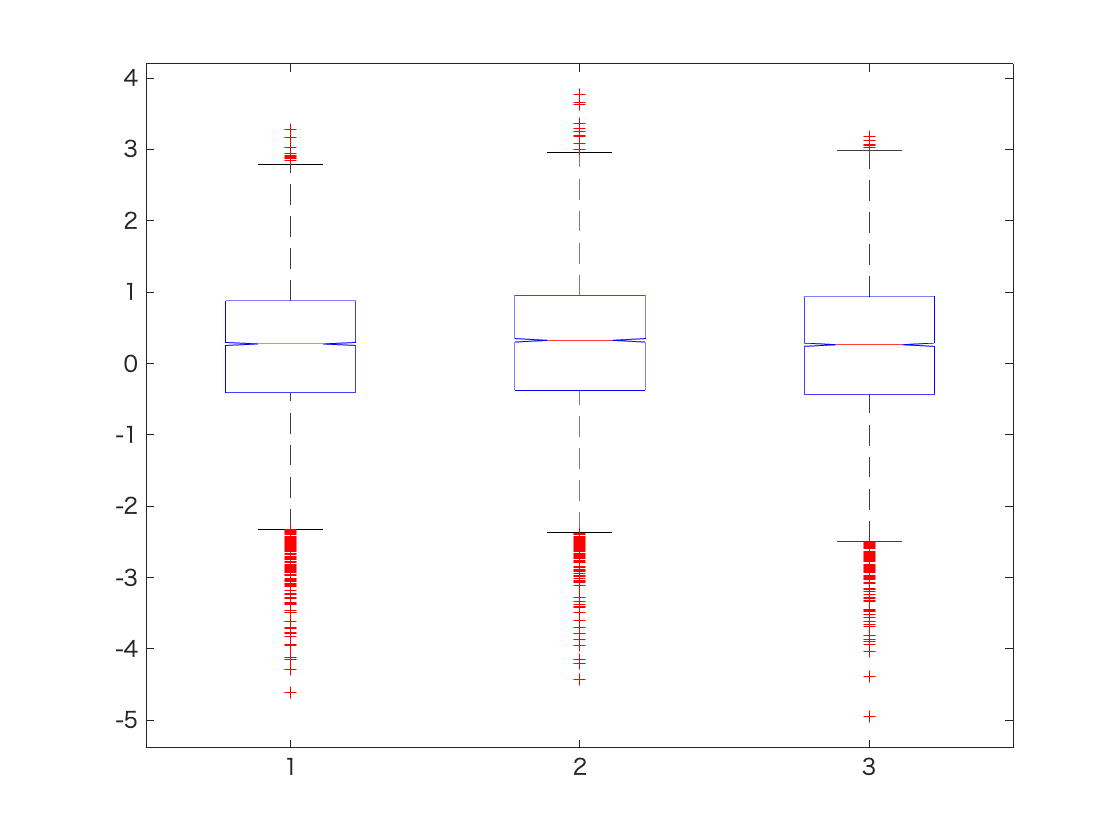

p = 5.6799e-04

tbl = 4×6 の cell 配列
    {'ソース'  }    {'SS'        }    {'df'   }    {'MS'        }    {'カイ 2 乗'}    {'確率>カイ 2 乗'}
    {'グループ'}    {[7.7534e+08]}    {[    2]}    {[3.8767e+08]}    {[ 14.9468]}    {[   5.6799e-04]}
    {'エラー'  }    {[1.2934e+12]}    {[24946]}    {[5.1846e+07]}    {0×0 double}    {0×0 double     }
    {'総数'   }    {[1.2941e+12]}    {[24948]}    {0×0 double  }    {0×0 double}    {0×0 double     }


stats = フィールドをもつ struct :
       gnames: {3×1 cell}
            n: [9058 7243 8648]
       source: 'kruskalwallis'
    meanranks: [1.2325e+04 1.2746e+04 1.2405e+04]
         sumt: 0



result = concatenateAndFill(x1, x2, x3);
[p,tbl,stats] = kruskalwallis(result)

メモ: 区間は検定に使用できますが、同時信頼区間ではありません。


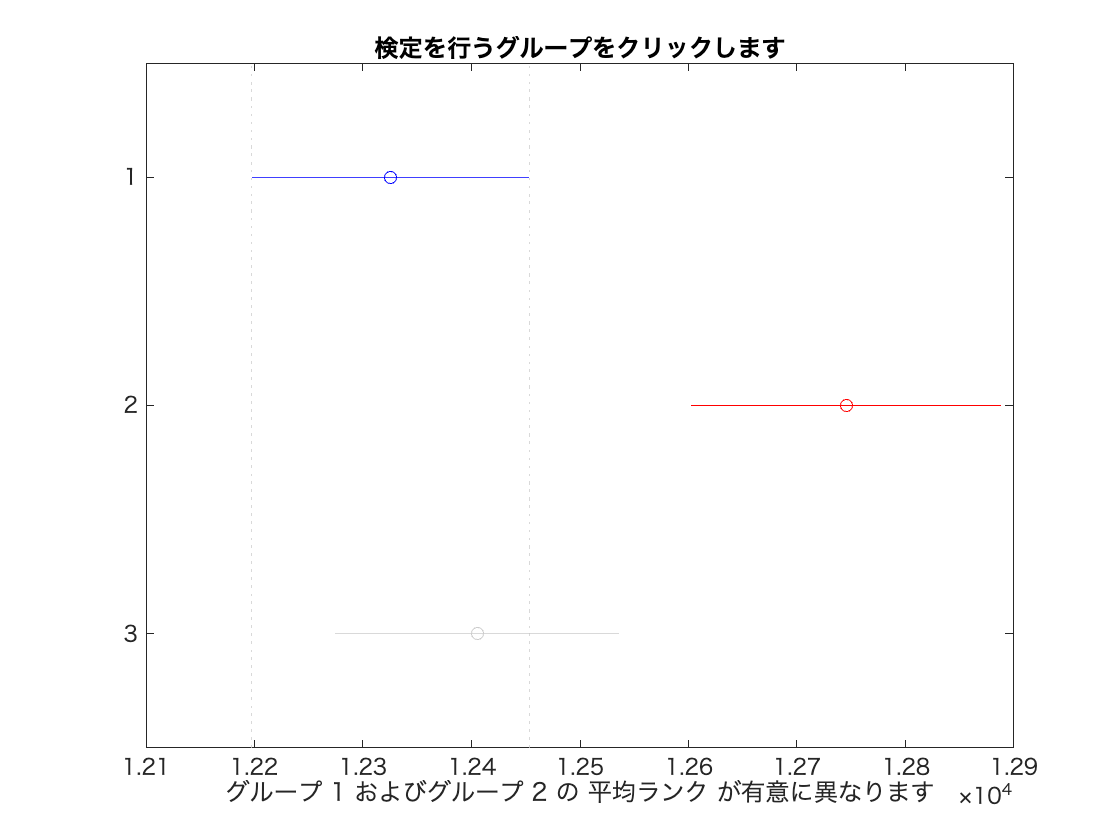

c =     1.0000    2.0000 -691.3337 -420.2587 -149.1836    0.0006
    1.0000    3.0000 -338.4401  -79.8903  178.6594    0.8431
    2.0000    3.0000   66.4529  340.3683  614.2837    0.0090


c = multcompare(stats,"CriticalValueType","dunn-sidak")

writematrix(result, "ANOVA.csv")